%  单面点云数据处理
%% 数据导入
clc;
clear all;
%单面点云拟合
filepath = "C:\Users\10571\Desktop\t1\轮廓法 ssy\20240311\JF14-00.txt";
Data = importdata(filepath);
x0 = Data(:,1); y0 = Data(:,3); z0 = -Data(:,2);
% 坐标原点平移到（0，0）;
n0 = length(x0);
a0 = [x0,y0,z0,ones(n0,1)];
u0 = [0,min(abs(y0)),-mean(z0)];
Tr0 = [1,0,0,0;0,1,0,u0(2);0,0,1,u0(3);0,0,0,1];
A0 = a0*Tr0';
Data = [A0(:,1),A0(:,2),A0(:,3)];
ImpData = Data;

## 双面点云拟合

% data1 = importdata("C:\Users\10571\Desktop\t1\轮廓法 ssy\621\EW6\EW6-A1B1(第二次).txt");
% data2 = importdata("C:\Users\10571\Desktop\t1\轮廓法 ssy\621\EW6\EW6-A2B2(第二次).txt");
% x0 = data1(:,1); y0 = data1(:,3); z0 = -data1(:,2);
% [x0,z0] = Re(x0,z0);
% x1 = data2(:,1); y1 = data2(:,3); z1 = -data2(:,2);
% [x1,z1] = Re(x1,z1);
% x = [-x1(x1>0);-x1(x1<0)]; y = [y1(x1>0);y1(x1<0)]; z = [z1(x1>0);z1(x1<0)];
% %%配准
% %坐标原点平移到（0，0）;
% n0 = length(x0); n1 = length(x);
% a0 = [x0,y0,z0,ones(n0,1)]; a1 = [x,y,z,ones(n1,1)];
% u0 = [0,min(abs(y0)),-mean(z0)]; u1 = [0,min(abs(y)),-mean(z)];
% Tr0 = [1,0,0,0;0,1,0,u0(2);0,0,1,u0(3);0,0,0,1]; Tr1 = [1,0,0,0;0,1,0,u1(2);0,0,1,u1(3);0,0,0,1];
% A0 = a0*Tr0'; A1 = a1*Tr1'; 
% %%%%
% data1 = [A0(:,1),A0(:,2),A0(:,3)];
% data2 = [A1(:,1),A1(:,2),A1(:,3)];
% ImpData = [data1;data2];
% x = ImpData(:,1); y = ImpData(:,2); z = ImpData(:,3);
% idx = y <= max(y) - 2;
% ImpData = [x(idx),y(idx),z(idx)];

## 前处理

d = 1;%网格大小
[xq, yq, zq] = PreprocessDate(ImpData,d);

## 拟合

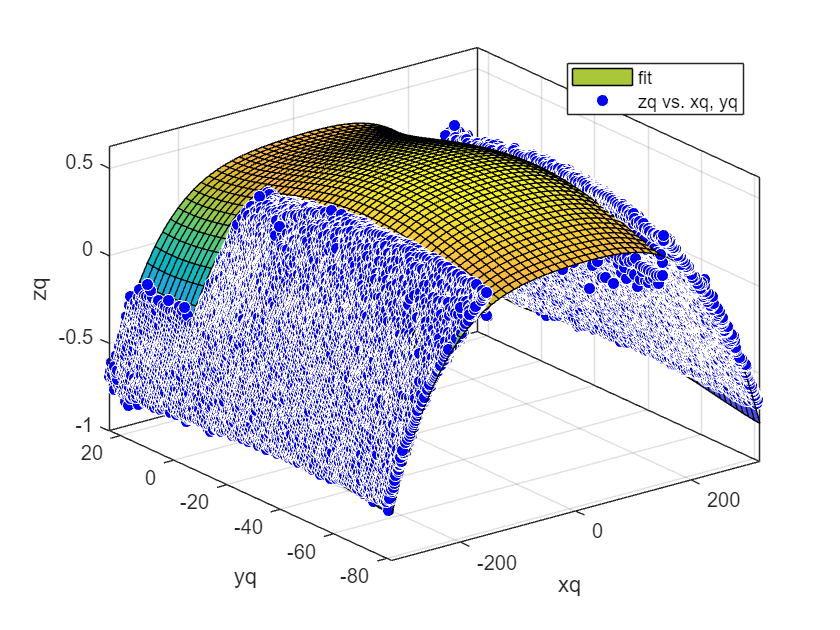

n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

0.49375 + -0.0056356*Y + 1.9178e-06*Y*Y + 2.2044e-06*Y*Y*Y + 1.4499e-08*Y*Y*Y*Y + -1.3436e-07*X*Y + -4.7718e-09*X*Y*Y + -9.4206e-12*X*Y*Y*Y + 3.5974e-08*X*X*Y + 5.3429e-10*X*X*Y*Y + 9.3277e-12*X*X*X*Y + -8.974e-11*X*X*X*X 


disp(gof)

           sse: 48.2700
       rsquare: 0.9869
           dfe: 30082
    adjrsquare: 0.9869
          rmse: 0.0401



%保存拟合结果到文本
c2 = cell2mat(struct2cell(gof));
a = {s;c2};
fileID = fopen(strcat(fileparts(filepath),'poly.txt'),'w');%%fileparts提取文件路径
formatSpec = '%s %d %2.1f %s\n';
[nrows,ncols] = size(a);
for row = 1:nrows
    fprintf(fileID,formatSpec,a{row,:}); % 注意此处不用{}，而是（）时，得到的字符串酱油引号，需注意
end
fclose(fileID);



